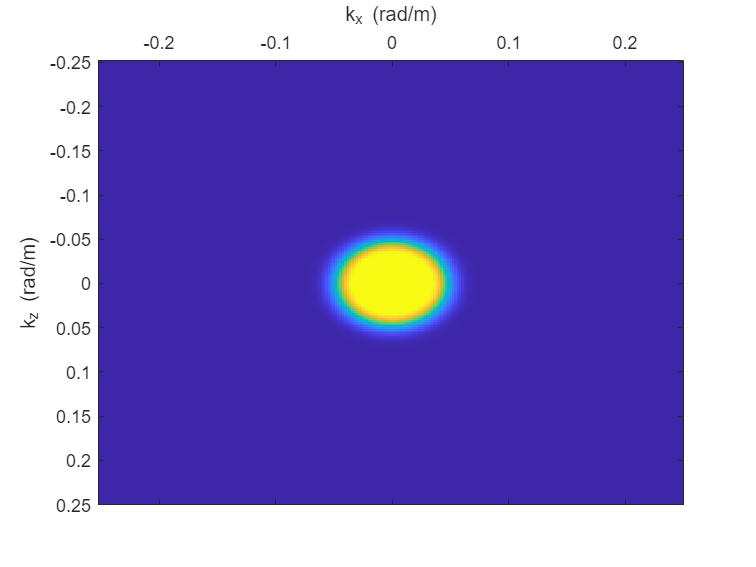

%computation domain
nz=250; nx=250;

%marmousi model
nx_m=281; nz_m=1361;
h=12.5; %meters
dx=h;

fileID = fopen('vp.12.5m');
vp0 = fread(fileID,'single');
vp1 = reshape(vp0,nx_m,nz_m);
vp = vp1(1:nx,600:600+nz-1);

fileID = fopen('rho.12.5m');
rho0 = fread(fileID,'single');
rho1 = reshape(rho0,nx_m,nz_m);
rho = rho1(1:nx,600:600+nz-1)/1000;

% global xp1 x xm1 zp1 z zm1;
[xp1, x, xm1, zp1, z, zm1] = initialize_D(nx,nz);

%time steps
nt=800; %1000;
dt=0.001; %sec

%peak frequency
fp=8; %Hz

%velocity range
vp=3000*ones(nz,nx);
% vp(3/5*nz:end,:)=3000;
vs=vp./1.7;
alpha = vs./vp;
% rho=1;
rho = ones(nz,nx);
% rho(3/5*nz:end,:)= 2;
%cmin=625.;
%cmax=1750.;
Q=50;
%Q=1000;

%source location
isz=nz/2; isx=nx/2;

kx = 2*pi*(-nx/2:nx/2-1) / (h*nx);   % kx in rad/m
kz = 2*pi*(-nz/2:nz/2-1) / (h*nz);   % kz in rad/m


[KX, KZ] = meshgrid(kx, kz);
K = sqrt(KX.^2 + KZ.^2);              % absolute wavenumber

k_cut = 2*pi*fp/min(vp,[],"all")*2;  % cutoff wavenumber (rad/m)
% mask = double(K <= k_cut);             % low-pass filter mask
mask = zeros(size(K));

% 完全保留区域：K <= k_cut
mask(K <= k_cut) = 1;

% 过渡区域：K > k_cut，平滑衰减
sigma_filter=0.5;
idx = (K > k_cut);
mask(idx) = exp( - ((K(idx) - k_cut) / (sigma_filter * k_cut)).^2 );
figure
imagesc(kz,kx,mask)
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')

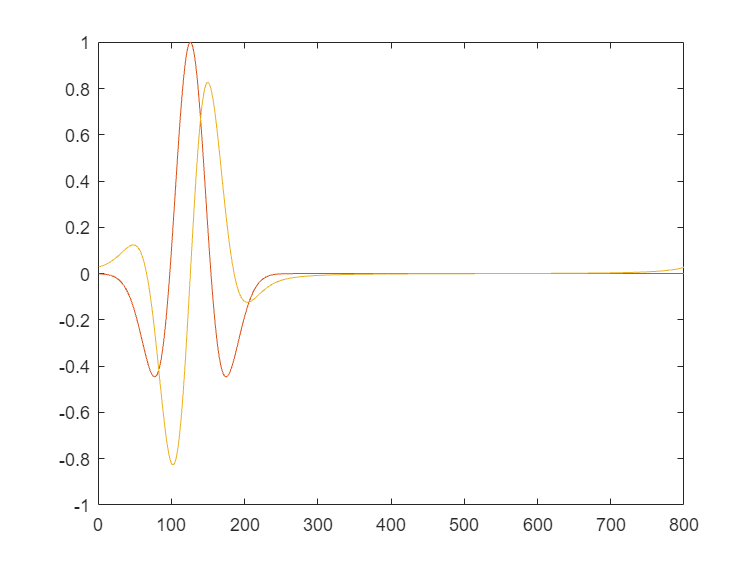


%source time function
figure
wl=ricker(fp,dt,nt);
plot(wl); hold on; 
plot(real(hilbert(wl)));
plot(imag(hilbert(wl)));

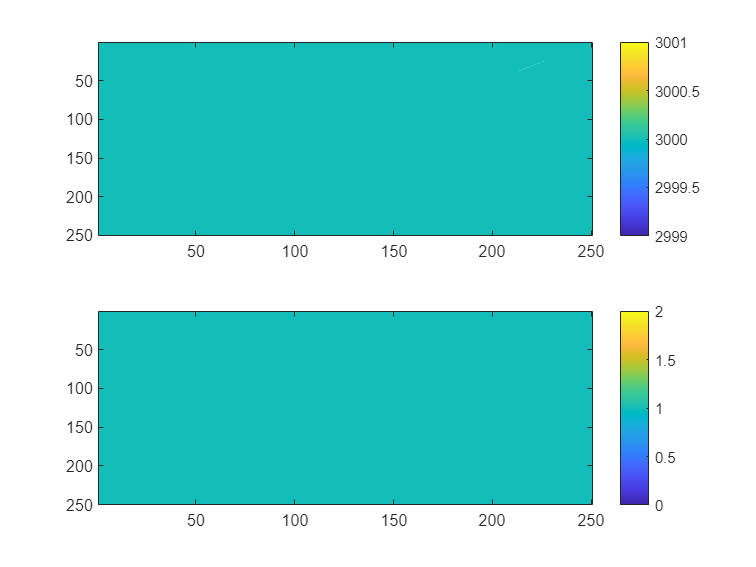

subplot(2,1,1)
imagesc(vp)
colorbar
subplot(2,1,2)
imagesc(rho)
colorbar

n = 256;
c1 = [linspace(0,1,n/2)', linspace(0,1,n/2)', ones(n/2,1)]; % 蓝到白
c2 = [ones(n/2,1), linspace(1,0,n/2)', linspace(1,0,n/2)']; % 白到红
seismicMap = [c1; c2];

[a_x00, a_z00, p00]=modeling_AC({vp,vs,rho,alpha,Q,mask},[0 0],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1});

NO Dispersion
NO Dissipation


it = 100

ans = 0

ans = -1.7956 - 7.2329i

it = 200

ans = 0

ans = -2.2831 + 0.1480i

it = 300

ans = -2.3601e-171 +6.9638e-170i

ans = 1.0077 - 0.6883i

it = 400

ans = -7.0304e-99 + 2.0009e-97i

ans = 0.8011 - 0.5497i

it = 500

ans = -4.3268e-54 + 1.1712e-52i

ans = 0.6762 - 0.4840i

it = 600

ans = -1.3139e-24 + 3.2563e-23i

ans = 0.5829 - 0.4530i

it = 700

ans = -5.1800e-07 + 9.6855e-06i

ans = 1.0793 - 0.7913i

it = 800

ans = -0.0011 + 0.0001i

ans = 0.9467 - 0.7925i

[a_x10, a_z10, p10]=modeling_AC({vp,vs,rho,alpha,Q,mask},[1 0],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1});

Has Dispersion
NO Dissipation


it = 100

ans = 0

ans = -1.7067 - 6.8733i

it = 200

ans = 0

ans = -2.1671 + 0.1448i

it = 300

ans = 2.0550e-165 +1.0839e-164i

ans = 0.9945 - 0.5831i

it = 400

ans = 3.0446e-93 + 1.1449e-92i

ans = 0.7033 - 0.5862i

it = 500

ans = 5.5229e-49 + 1.6033e-48i

ans = 0.5860 - 0.5178i

it = 600

ans = 2.3570e-20 + 5.5532e-20i

ans = -0.8053 - 0.3330i

it = 700

ans = 2.4351e-04 + 4.9975e-04i

ans = 0.9285 - 0.8489i

it = 800

ans = -0.0015 + 0.0038i

ans = -1.1303 + 0.2254i

[a_x01, a_z01, p01]=modeling_AC({vp,vs,rho,alpha,Q,mask},[0 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1});

NO Dispersion
Has Dissipation


it = 100

ans = 0

ans = -1.9319 - 7.1945i

it = 200

ans = -7.1616e-08 - 2.7502e-07i

ans = -2.3471 + 0.1987i

it = 300

ans = 1.7862e-07 + 3.6758e-07i

ans = 0.9241 - 0.6286i

it = 400

ans = -6.3428e-07 + 2.5271e-08i

ans = 0.6706 - 0.5149i

it = 500

ans = -5.1208e-06 - 3.7024e-06i

ans = 0.5336 - 0.4341i

it = 600

ans = -6.9750e-06 + 2.3856e-05i

ans = -0.5728 - 0.1599i

it = 700

ans = 7.9630e-05 + 4.4533e-05i

ans = 0.7954 - 0.6138i

it = 800

ans = -0.0011 - 0.0001i

ans = 0.7266 - 0.4998i

[a_x11, a_z11, p11]=modeling_AC({vp,vs,rho,alpha,Q,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1});

Has Dispersion
Has Dissipation


it = 100

ans = 0

ans = -1.8466 - 6.8357i

it = 200

ans = -7.2295e-08 - 2.2259e-07i

ans = -2.1741 + 0.3076i

it = 300

ans = 8.4548e-08 - 1.1622e-07i

ans = 0.9302 - 0.4888i

it = 400

ans = -9.5956e-07 - 9.5370e-07i

ans = 0.6376 - 0.4689i

it = 500

ans = 1.8688e-06 - 2.0107e-06i

ans = 0.4968 - 0.4061i

it = 600

ans = -9.4644e-08 - 3.9791e-06i

ans = -0.6135 - 0.3171i

it = 700

ans = -0.0042 + 0.0009i

ans = 0.7262 - 0.5839i

it = 800

ans = -0.0013 + 0.0036i

ans = -0.8488 + 0.0321i

% [~, ~, p_Q500]=modeling_AC({vp,vs,rho,alpha,500,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1});
% [~, ~, p_Q100]=modeling_AC({vp,vs,rho,alpha,100,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1});
% [~, ~, p_Q20]=modeling_AC({vp,vs,rho,alpha,20,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1});
p11_TDCV=modeling_TDCV({vp,vs,rho,Q,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1, h});

Has Dispersion
Has Dissipation


it = 100

ans = -3.1485e-10 + 1.7272e-09i

ans = -1.7174 - 6.8597i

it = 200

ans = -2.5768e-07 + 8.7428e-08i

ans = -2.1665 + 0.1483i

it = 300

ans = -4.1403e-06 - 6.4076e-07i

ans = 0.9422 - 0.4856i

it = 400

ans = -2.7410e-05 - 6.5959e-06i

ans = 0.6655 - 0.4455i

it = 500

ans = -1.3315e-04 - 1.3225e-05i

ans = 0.5141 - 0.4010i

it = 600

ans = -6.1529e-04 + 9.0574e-05i

ans = -0.6048 - 0.3364i

it = 700

ans = -0.0018 + 0.0048i

ans = 0.6955 - 0.6286i

it = 800

ans = 0.0047 + 0.0007i

ans = -0.8494 + 0.0021i

p_sls=modeling_GSLS({vp,rho},{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1});

it = 100

ans = -2.2953

ans = 0

it = 200

ans = -2.2366

ans = 1.8206

it = 300

ans = -0.5683

ans = 1.0669

it = 400

ans = -0.4523

ans = 0.7966

it = 500

ans = -0.3785

ans = 0.6449

it = 600

ans = -0.6358

ans = 0.5428

it = 700

ans = -0.5722

ans = 0.9370

it = 800

ans = -0.8857

ans = 0.8181

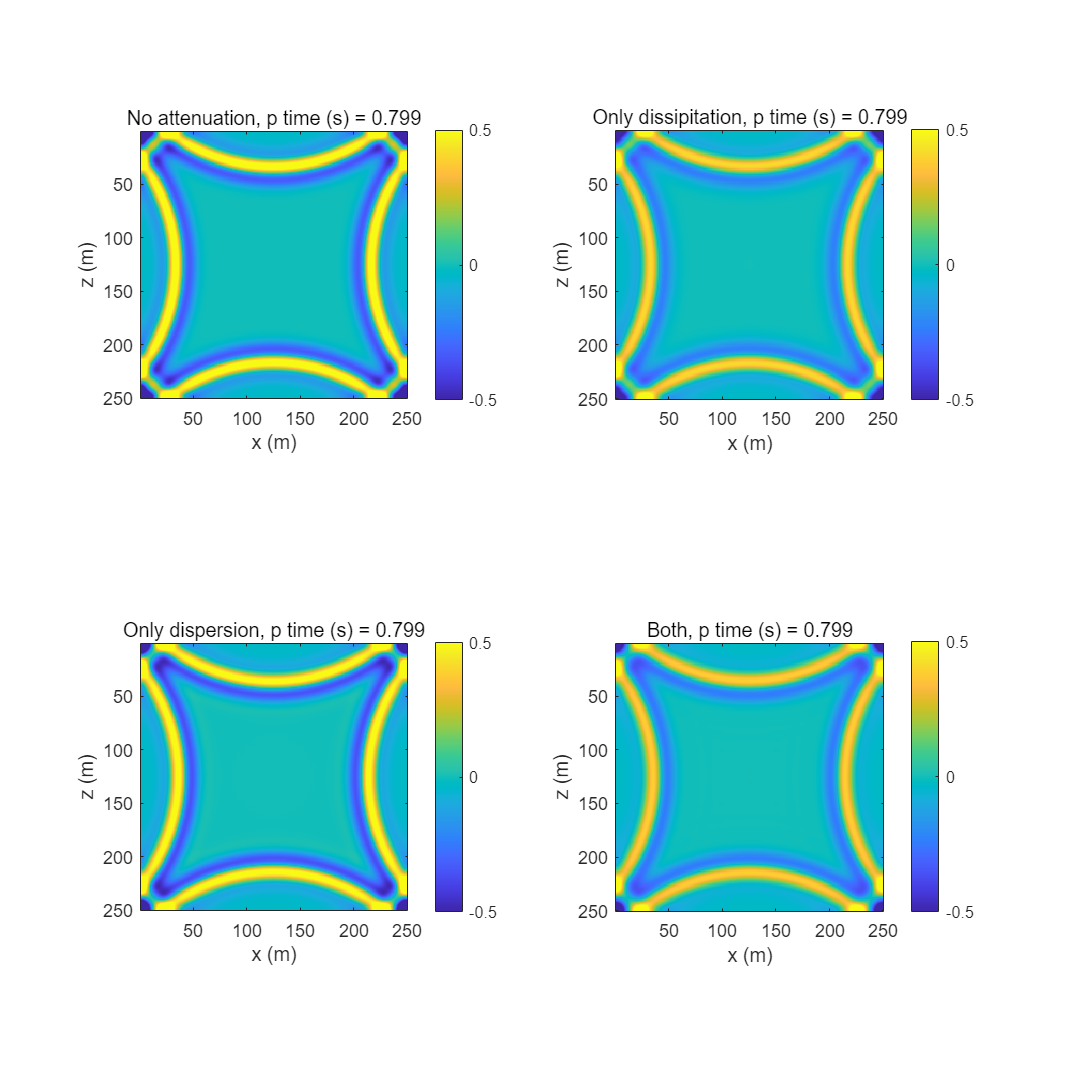

figure('Position',[400 400 800 800])
clip=0.5;
for i = 1:nt
    if rem(i,50)==0
        subplot(2,2,1)
        imagesc(real(squeeze(p00(:,:,i))))
        colorbar
        axis equal
        axis tight
        clim([-clip clip]) % for 'ricker' source
        title(['No attenuation, p time (s) = ' , num2str((i-1)*dt)])
        xlabel('x (m)'), ylabel('z (m)')   

        subplot(2,2,2)
        imagesc(real(squeeze(p01(:,:,i))))
        colorbar
        axis equal
        axis tight
        clim([-clip clip]) % for 'ricker' source
        title(['Only dissipitation, p time (s) = ' , num2str((i-1)*dt)])
        xlabel('x (m)'), ylabel('z (m)')   

        subplot(2,2,3)
        imagesc(real(squeeze(p10(:,:,i))))
        colorbar
        axis equal
        axis tight
        clim([-clip clip]) % for 'ricker' source
        title(['Only dispersion, p time (s) = ' , num2str((i-1)*dt)])
        xlabel('x (m)'), ylabel('z (m)')   

        subplot(2,2,4)
        imagesc(real(squeeze(p11(:,:,i))))
        colorbar
        axis equal
        axis tight
        clim([-clip clip]) % for 'ricker' source
        title(['Both, p time (s) = ' , num2str((i-1)*dt)])
        xlabel('x (m)'), ylabel('z (m)')   
        pause(0.01)

    end
end

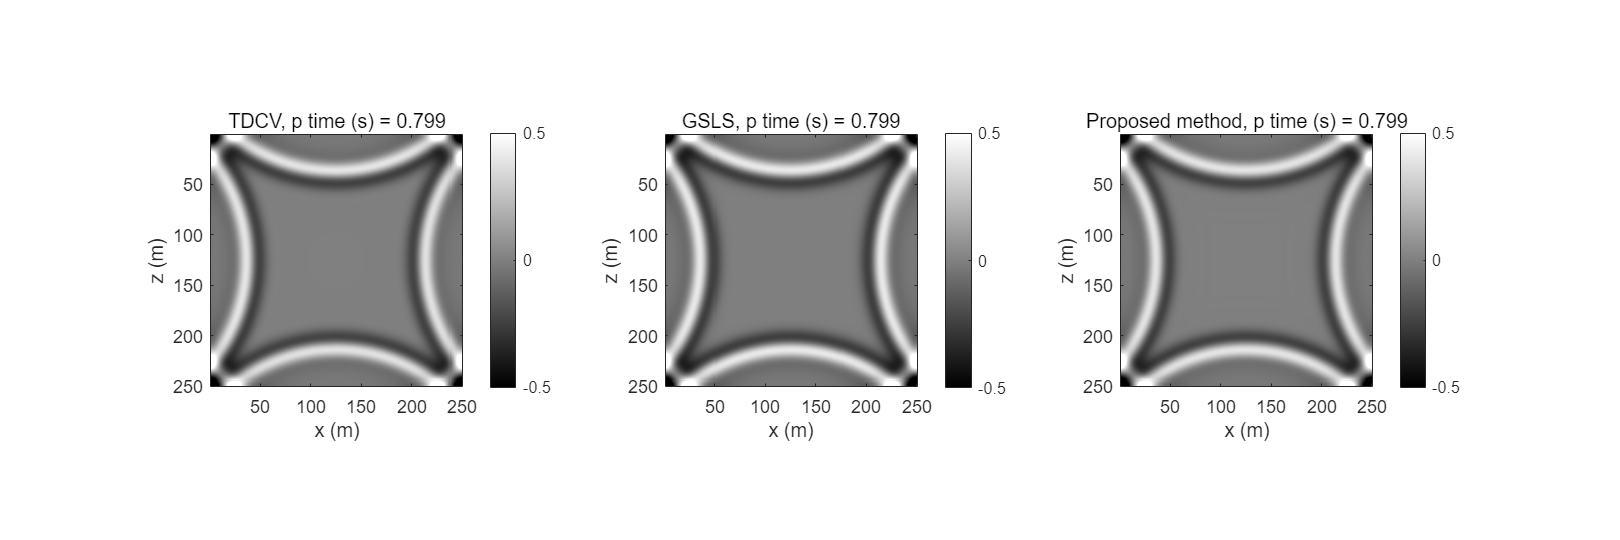

figure('Position',[400 400 1200 400])
clip=0.5;
for i = 1:nt
    if rem(i,50)==0
        subplot(1,3,1)
        imagesc(real(squeeze(p11_TDCV(:,:,i))))
        colorbar
        axis equal
        axis tight
        clim([-clip clip]) % for 'ricker' source
        title(['TDCV, p time (s) = ' , num2str((i-1)*dt)])
        colormap('gray')
        xlabel('x (m)'), ylabel('z (m)')   

        subplot(1,3,2)
        imagesc(real(squeeze(p_sls(:,:,i))))
        colorbar
        axis equal
        axis tight
        clim([-clip clip]) % for 'ricker' source
        title(['GSLS, p time (s) = ' , num2str((i-1)*dt)])
        colormap('gray')
        xlabel('x (m)'), ylabel('z (m)') 

        subplot(1,3,3)
        imagesc(real(squeeze(p11(:,:,i))))
        colorbar
        axis equal
        axis tight
        clim([-clip clip]) % for 'ricker' source
        title(['Proposed method, p time (s) = ' , num2str((i-1)*dt)])
        colormap('gray')
        xlabel('x (m)'), ylabel('z (m)') 

        pause(0.01)

    end
end

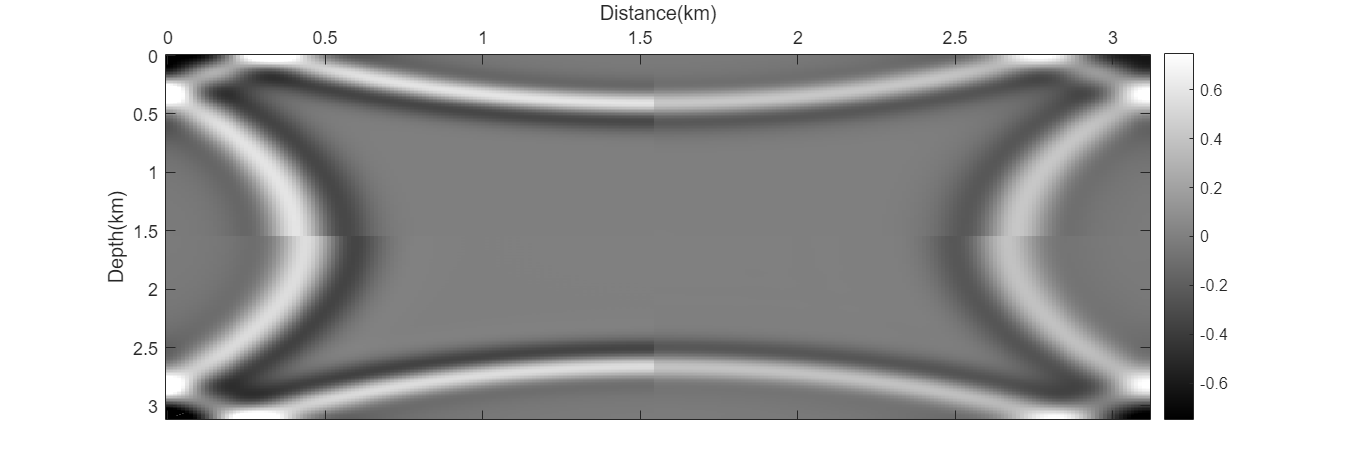


x = (0:nx-1)*h/1000;
z = (0:nz-1)*h/1000;
figure('Position', [400 400 400 350]);
clip=0.75;
for i = 1:nt
    if rem(i,50)==0
        combined=squeeze(p00(:,:,i));
        combined(nz/2:nz,1:nx/2)=p10(nz/2:nz,1:nx/2,i); %dispersion
        combined(1:nz/2,nx/2:nx)=p01(1:nz/2,nx/2:nx,i); %dissipation
        combined(nz/2:nz,nx/2:nx)=p11(nz/2:nz,nx/2:nx,i);

        % combined2=squeeze(p_Q500(:,:,i));
        % combined2(nz/2:nz,1:nx/2)=p11(nz/2:nz,1:nx/2,i); %dispersion
        % combined2(1:nz/2,nx/2:nx)=p_Q100(1:nz/2,nx/2:nx,i); %dissipation
        % combined2(nz/2:nz,nx/2:nx)=p_Q20(nz/2:nz,nx/2:nx,i);
        % subplot(1,2,1)
        imagesc(x,z,real(combined),[-clip,clip]) ;
        xlabel('Distance(km)')
        ylabel('Depth(km)')
        set(gca,'xaxisLocation','top')
        colorbar
        colormap('gray')

        % subplot(1,2,2)
        % imagesc(x,z,real(combined2),[-clip,clip]) ;
        % xlabel('Distance(km)')
        % ylabel('Depth(km)')
        % set(gca,'xaxisLocation','top')
        % colorbar
        % colormap('gray')
        pause(0.01);
    end
end

% figure('Position', [400 400 400 350]);
% clip=0.75;
% for i = 1:nt
%     if rem(i,50)==0
% 
%         imagesc(x,z,real(combined),[-clip,clip]) ;
%         xlabel('Distance(km)')
%         ylabel('Depth(km)')
%         set(gca,'xaxisLocation','top')
%         colormap('gray')
%         colorbar
%         pause(0.01);
%     end
% end

% figure('Position', [400 400 400 350]);
% clip=0.75;
% for i = 1:nt
%     if rem(i,50)==0
%         combined=squeeze(p11_TDCV(:,:,i)); % TDCV 
%         combined(:,nx/2:end)=squeeze(p_sls(:,nx/2:end,i)); %GSLS
%         combined(nz/2:nz,:)=squeeze(p11(nz/2:nz,:,i)); % our method
%         imagesc(x,z,real(combined),[-clip,clip]) ;
%         xlabel('distance(km)')
%         ylabel('depth(km)')
%         set(gca,'xaxisLocation','top')
%         colorbar
%         pause(0.01);
%     end
% end

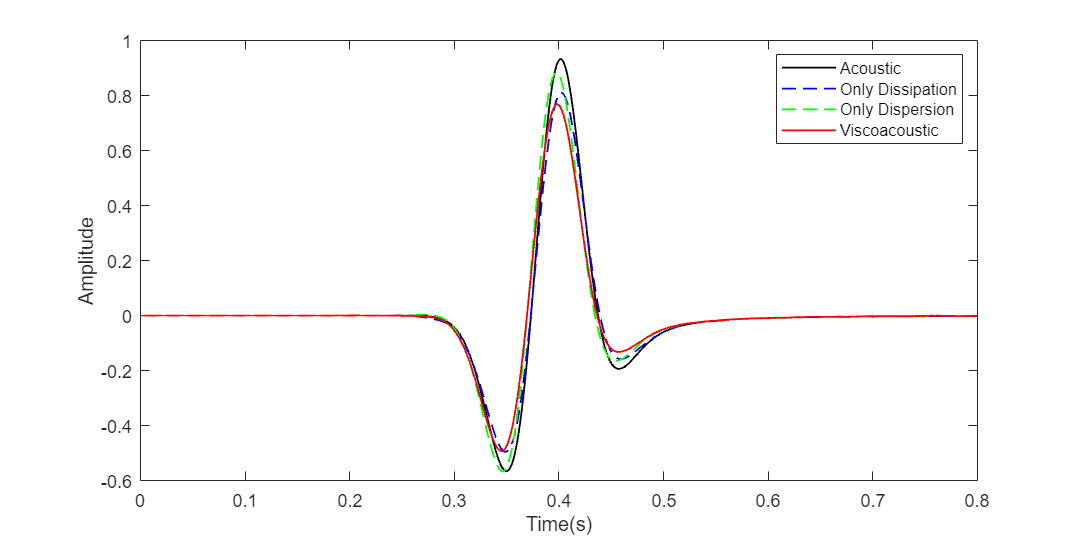

% close(v);

figure('Position',[400 400 800 400])
location_x = 80;
location_z = 80;
plot(linspace(0,nt*dt,nt), squeeze(real(p00(location_z,location_x,:))), '-','Color', 'k','LineWidth',1); hold  on;
plot(linspace(0,nt*dt,nt), squeeze(real(p01(location_z,location_x,:))), '--','Color', 'blue','LineWidth',1); hold  on;
plot(linspace(0,nt*dt,nt), squeeze(real(p10(location_z,location_x,:))), '--','Color', 'green','LineWidth',1); hold  on;
plot(linspace(0,nt*dt,nt), squeeze(real(p11(location_z,location_x,:))),'Color', 'red','LineWidth',1);
% plot(linspace(0,nt*dt,nt), squeeze(real(p11_TDCV(location_z,location_x,:))),'Color', 'c','LineWidth',1); hold  on;
% plot(linspace(0,nt*dt,nt), squeeze(p_sls(location_z,location_x,:)), 'Color', 'm','LineWidth',1); 
xlabel('Time(s)')
ylabel('Amplitude')
% set(gca, 'YDir', 'reverse');
legend('Acoustic','Only Dissipation', 'Only Dispersion', 'Viscoacoustic')

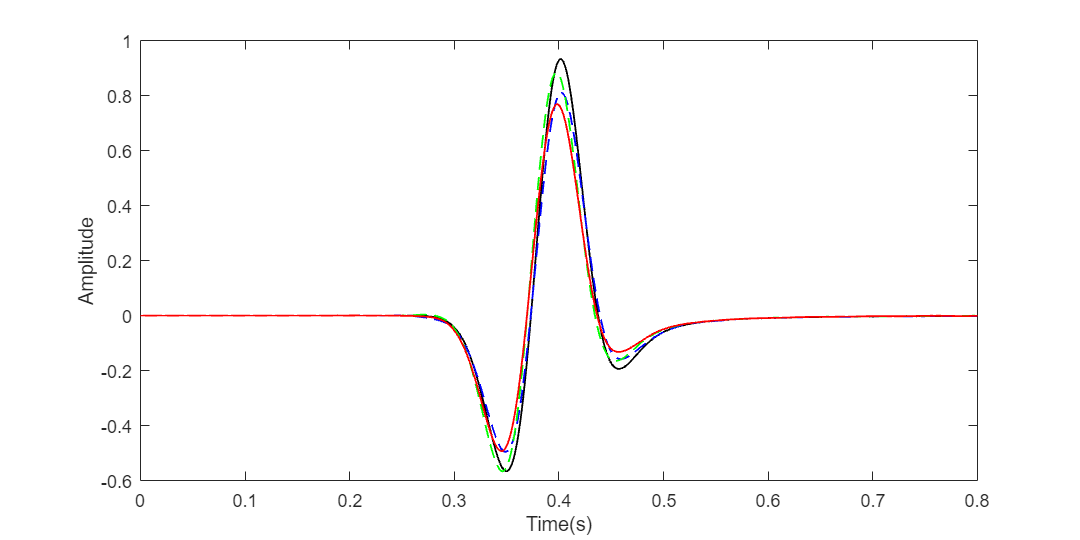

% figure('Position',[400 400 800 400])
% location_x = 80;
% location_z = 80;
% plot(linspace(0,nt*dt,nt), squeeze(real(p00(location_z,location_x,:))), '-','Color', 'k','LineWidth',1); hold  on;
% plot(linspace(0,nt*dt,nt), squeeze(real(p01(location_z,location_x,:))), '--','Color', 'blue','LineWidth',1); hold  on;
% plot(linspace(0,nt*dt,nt), squeeze(real(p10(location_z,location_x,:))), '--','Color', 'green','LineWidth',1); hold  on;
% plot(linspace(0,nt*dt,nt), squeeze(real(p11(location_z,location_x,:))),'Color', 'red','LineWidth',1);
% xlabel('Time(s)')
% ylabel('Amplitude')

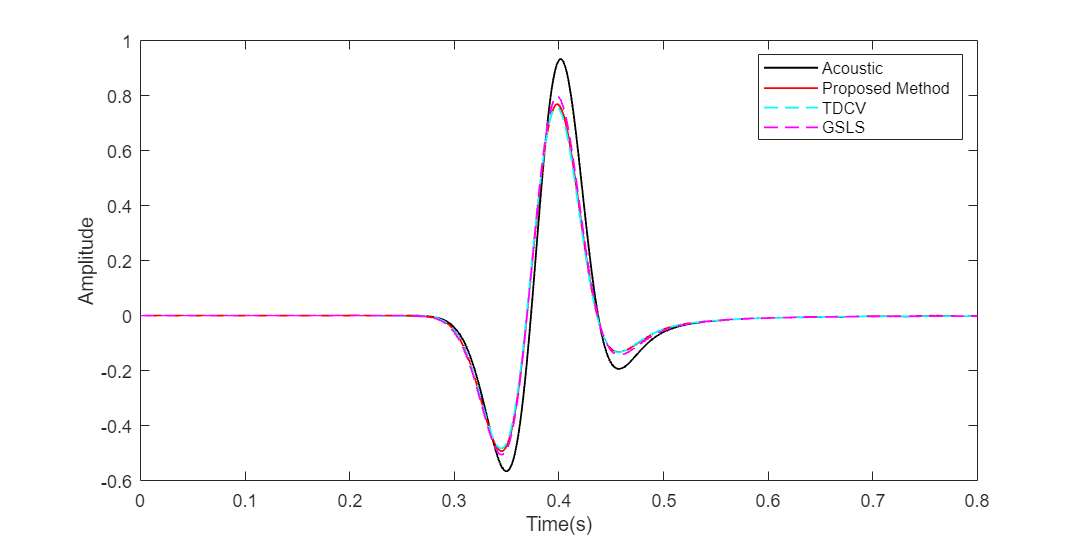


figure('Position',[400 400 800 400])
location_x = 80;
location_z = 80;
plot(linspace(0,nt*dt,nt), squeeze(real(p00(location_z,location_x,:))), '-','Color', 'k','LineWidth',1); hold  on;
plot(linspace(0,nt*dt,nt), squeeze(real(p11(location_z,location_x,:))),'Color', 'red','LineWidth',1); hold  on;
plot(linspace(0,nt*dt,nt), squeeze(real(p11_TDCV(location_z,location_x,:))),'--','Color', 'c','LineWidth',1); hold  on;
plot(linspace(0,nt*dt,nt), squeeze(p_sls(location_z,location_x,:)), '--','Color', 'm','LineWidth',1); 
xlabel('Time(s)')
ylabel('Amplitude')
% set(gca, 'YDir', 'reverse');
legend('Acoustic','HTCV','TDCV','GSLS')

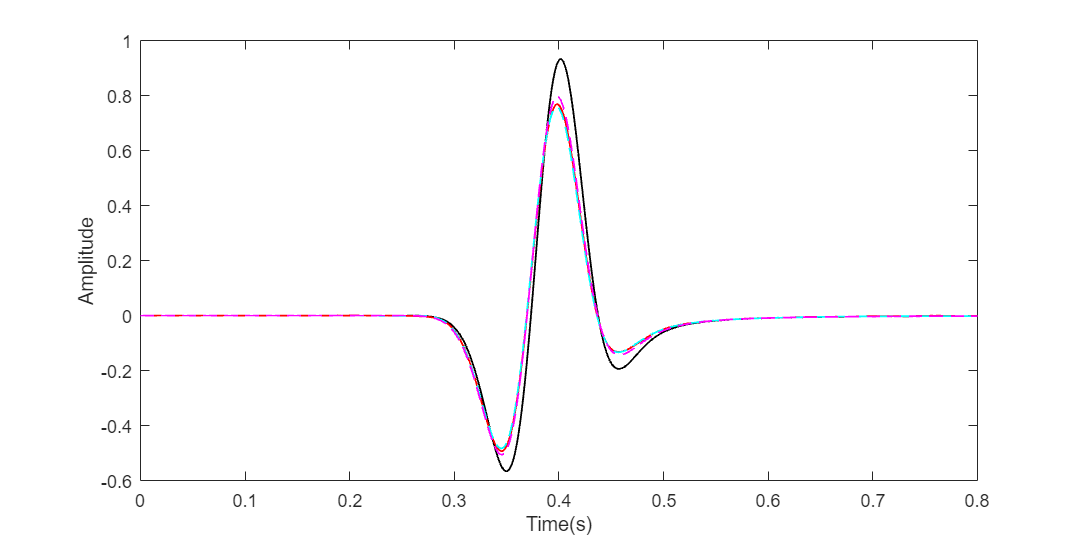

figure('Position',[400 400 800 400])
location_x = 80;
location_z = 80;
plot(linspace(0,nt*dt,nt), squeeze(real(p00(location_z,location_x,:))), '-','Color', 'k','LineWidth',1); hold  on;
plot(linspace(0,nt*dt,nt), squeeze(real(p11(location_z,location_x,:))),'Color', 'red','LineWidth',1); hold  on;
plot(linspace(0,nt*dt,nt), squeeze(real(p11_TDCV(location_z,location_x,:))),'--','Color', 'c','LineWidth',1); hold  on;
plot(linspace(0,nt*dt,nt), squeeze(p_sls(location_z,locatiUnder homogeneous model conditions with Q=50Q=50
Q=50, a comparison of single-trace seismic records obtained by the HTCV method. (a) The effects of the dispersion and dissipation terms. (b) Comparison with TDCV and GSLS. The attenuation results of HTCV are consistent with those of other methods.on_x,:)), '--','Color', 'm','LineWidth',1); 
xlabel('Time(s)')
ylabel('Amplitude')

## **For 2 Step AC FD modeling**


$$\rho a = \nabla p$$



$$\ddot p = \kappa \nabla a$$


staggered grids

1         --------     --------

        |                |            |

 $\frac{1}{2}$   $a_{z}$ --------     --------

        |                |            |

        $p_{ii}$ -------- $a_{x}$--------

    0                 $\frac{1}{2}$             1

matrix form 


$$M \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  (\ddot p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


$M=\left [ \matrix{diag(\rho) & 0 \cr 0 & \kappa ^{-1}} \right ]$, $N=M^{-1}=\left [ \matrix{diag(b) & 0 \cr 0 & \kappa} \right ]$, $D=\left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ]$.

Fourier transform


$$\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & -\frac{\omega^2}{\kappa }} \right ] \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  ( p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


Kolsky-Futterman model: $c(\omega)=c(\omega_0)\left[1+\frac{1}{\pi Q}\ln\frac{\omega}{\omega_0}-\frac{i\text{sgn}(\omega)}{2Q}\right]$, or $\frac{1}{c(\omega)^2}=\frac{1}{c(\omega_0)^2}\left[1-\frac{2}{\pi Q}\ln\frac{\omega}{\omega_0}+\frac{i\text{sgn}(\omega)}{Q}\right]$ 


$$\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & -\frac{\omega^2}{\kappa_0 }\left[1-\frac{2}{\pi Q}\ln\frac{\omega}{\omega_0}+\frac{i\text{sgn}(\omega)}{Q}\right]} \right ] \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  (p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


Use approximation: $\omega^2\ln\frac{\omega}{\omega_0}\approx a\omega^2+b\omega+d$, where $a=5.7356, b=-762.1606, d=4.6054\times10^4$


$$\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & -\frac{1}{\kappa_0 }\left[ \left( 1 -\frac{2a}{\pi Q} -\frac{i}{Q}  \right)\omega^2-\frac{2b}{\pi Q}\omega - \frac{2d}{\pi Q} \right] } \right ] \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  (p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


Inverse Fourier Transform


$$\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & \frac{1}{\kappa_0 }\left[ \left( 1 -\frac{2a}{\pi Q} -\frac{i}{Q}  \right)\partial_{tt}-\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right] } \right ] \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  ( p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


$C1=1-\frac{2a}{\pi Q} - \frac{i}{Q} - \frac{bi}{\pi Q}\Delta t$, $C2=2(1-\frac{2a}{\pi Q} - \frac{i}{Q}-\frac{d}{\pi Q}\Delta t^2)$, $C3=- \left(1 - \frac{2a}{\pi Q} - \frac{i}{Q} + \frac{bi}{\pi Q} \Delta t \right )$

Time marching


$$\left [ \matrix{(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  (C_1p^_{n+1})_{i,j}} \right ] = \left [ \matrix{0 \cr 0 \cr C_2p^n + C_3p^{n-1}} \right ] + M^{-1} \left [ \matrix{\partial_z^f (p^n)_{i,j} \cr \partial _x^f (p^n)_{i,j} \cr \Delta t^2(\partial_z^b (a_z^n)_{i+1/2,j} + \partial_x^b (a_x^n)_{i,j+1/2})} \right] + M^{-1}f \Delta t^2$$


integration by parts:

$\int a^HM\partial_tudt = a^HMu|_{t=0}^T - \int(\partial_ta^H)Mudt$, $a(t=0)=0$ and $a(t=T)=0$(final condation)


$$\int a^HM\partial_tudt = - \int (\partial_ta^H)Mudt$$



$$\int a^HM\partial_{tt}udt = a^HM\partial_tu|_{t=0}^T - \int(\partial_ta^H)M\partial_tudt = a^HM\partial_tu|_{t=0}^T - (\partial_ta^H)Mu|_{t=0}^T + \int(\partial_{tt}a^H)Mudt = \int(\partial_{tt}a^H)Mudt$$


forward $p$: $\frac{1}{{\kappa_0 }}\left[ \left( 1 -\frac{2a}{\pi Q} -\frac{i}{Q}  \right)\partial_{tt}-\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right]$

adjoint $p^a$: $\frac{1}{{\kappa_0 }}\left[ \left( 1 -\frac{2a}{\pi Q} +\frac{i}{Q}  \right)\partial_{tt}-\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right]$ (for adjoint wave, consider transpose and conjugate, according to defination of inner product. Both adjoint wave and kernal should consider this)

For the inverse time direction of $\partial_t a$, in code, it leads to:

adjoint $p^a$: $\frac{1}{{\kappa_0 }}\left[ \left( 1 -\frac{2a}{\pi Q} +\frac{i}{Q}  \right)\partial_{tt}+\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right]$

Also, for spatial derivatives:


$$\int a^HDudx^3 = -\int (D^Ha)^Hudx^3$$


Therefore, $A^Ha= M^Ha+D^Ha=M^Ha-D^*a$, where $M^H=
\matrix{\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & \frac{1}{\kappa_0 }\left[ \left( 1 -\frac{2a}{\pi Q} +\frac{i}{Q}  \right)\partial_{tt}+\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right] } \right ]}$, $D^*=conjugate(D)$. 

There are 3 steps which need to consider + or -.

1. conjugate for inner product

2. intergration by parts

3. time direction for finite difference. $\partial_tu=\frac{u_{t+1}-u_{t}}{\Delta t}$, $\partial_ta=\frac{a_{t}-a_{t+1}}{\Delta t}=-\frac{a_{t+1}-a_{t}}{\Delta t}$

Gradient:

Since the ajoint wave is complex number, we consider conjugate wave: $a \rightarrow \overline a$


$$K_m<a|Au>=K_m<a| Mu +Du>$$


For $\rho$:

$g_{\rho}= a^{ajoint,H}a= a^{ajoint,H}b\nabla p$, note: here $a$ is acceleration.

For $\kappa$:


$$g_{\kappa}=p^{ajoint,H}(-\kappa ^{-2})\left[ \left( 1 -\frac{2a}{\pi Q} -\frac{i}{Q}  \right)\partial_{tt}+\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right]p =  p^{ajoint,H}(-\kappa^{-1})\nabla a$$


For $Q$:


$$g_Q=\overline p^{ajoint}\frac{1}{\kappa_0} \left [ (\frac{2a}{\pi Q^2}+\frac{i}{Q^2}) \partial_{tt} - \frac{2b}{\pi Q^2}\partial_t - \frac{2d}{\pi Q^2} \right ] p$$


function [a_log_x, a_log_z, p_log]=modeling_AC(model,mode,spatial_grid,source,temporal_grid,space_grid)
    
    %model
    vp=model{1};
    vs=model{2};
    rho=model{3};
    alpha=model{4};
    Q=model{5};
    mask=model{6};

    xp1=space_grid{1};
    x=space_grid{2};
    xm1=space_grid{3};
    zp1=space_grid{4};
    z=space_grid{5};
    zm1=space_grid{6};

    % mu = vs^2*rho;
    kappa = vp.^2.*rho;
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    wl_hilbert=hilbert(source{1});
    src=wl_hilbert;
    % src = source{1};
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    

    %KF model
    if mode(1)~=0
        % a=5.7356; b=-762.1606; d=4.6054e4;
        a = 3.7801; b=-110.6870; d=1111.5;
        disp('Has Dispersion');
    else
        a=0.; b=0.; d=0.;
        disp('NO Dispersion');
    end
    if mode(2)~=0
        e=1; disp('Has Dissipation');
    else
        e=0; disp('NO Dissipation');
    end

    C1= (1 -2*a/pi/Q -e*1i/Q -b*1i/pi/Q*dt);
    C1=1./C1;
    C2= (1 -2*a/pi/Q -e*1i/Q              -d/pi/Q*dt*dt)*2;
    C3=-(1 -2*a/pi/Q -e*1i/Q +b*1i/pi/Q*dt);
    % C1= 1;
    % C2= 1;
    % C3= 1;
    
    %wavefields
    a_log_x = complex(zeros(nz,nx,nt));
    a_log_z = complex(zeros(nz,nx,nt));
    p=complex(zeros(nz,nx));
    % pnew=zeros(nz,nx);
    pold=complex(zeros(nz,nx));
    pnew=complex(zeros(nz,nx));
    p_log=zeros(nz,nx,nt);
    % acceleration_dx=complex(zeros(nz,nx));
    % acceleration_dz=complex(zeros(nz,nx));
    % E=complex(zeros(2,2,nz,nx)); 
    % sigma=complex(zeros(2,2,nz,nx));

    %auxiliary variables
    r=vp*dt; r2=r.*r;
        
    % %smoothing
    sigma=2;
    ismth_start=ceil(2/fp/dt);
    ismth=100;
    
    %Mur ABC
    % [c1,c2,c3,c4]=abc_coef(r,r2);
    rho=1;
    rhoi = 1./rho;
    for it=1:nt
      
        %if(mod(it,100)==0) disp(it), end
        if(mod(it,100)==0)
            it,min(pnew(:,:),[],'all','includenan'),max(pnew(:,:),[],'all','includenan')
        end

        p(izs,ixs) = p(izs,ixs)+src(it);
        

        acceleration_dx = rhoi.*(D(0,1,p, xp1, x, xm1, zp1, z, zm1, h));
        acceleration_dz = rhoi.*(D(1,1,p, xp1, x, xm1, zp1, z, zm1, h));

        % acceleration_dz(izs,ixs) = acceleration_dz(izs,ixs)+src(it);

        pnew = C1.*(C2.*p + C3.*pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,xp1, x, xm1, zp1, z, zm1, h) ...
                                                   + D(1,-1,acceleration_dz,xp1, x, xm1, zp1, z, zm1, h)));
        % pnew = 2*p - pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,xp1, x, xm1, zp1, z, zm1, h) ...
        %                                            + D(1,-1,acceleration_dz,xp1, x, xm1, zp1, z, zm1, h));

        % acceleration=acceleration_dx+acceleration_dz;
        % if mode(2)~=0
        %     if it>=ismth_start
        %         if mod(it,ismth)==0
        %             p(:,:)=complex(imgaussfilt(real(p(:,:)),sigma), imgaussfilt(imag(p(:,:)),sigma));
        %             pnew(:,:)=complex(imgaussfilt(real(pnew(:,:)),sigma), imgaussfilt(imag(pnew(:,:)),sigma));
        %         end
        %     end
        % end

        if mode(2)~=0
            if mod(it,ismth)==0
                pnew = fft_filter(pnew, mask);
                p = fft_filter(p, mask);
            end
        end

        pold(:,:) = p(:,:) ;
        p(:,:)  = pnew(:,:) ;

        p_log(:,:,it)= pnew;
        a_log_x(:,:,it)= acceleration_dx;
        a_log_z(:,:,it)= acceleration_dz;

        % %strain
        % E(1,1,:,:)= D(0,-1,squeeze(U(1,:,:,it)), xp1, x, xm1, zp1, z, zm1, h);
        % E(2,2,:,:)= D(1,-1,squeeze(U(2,:,:,it)), xp1, x, xm1, zp1, z, zm1, h);
        % E(1,2,:,:)= 1/2*(D(1,1,squeeze(U(1,:,:,it)), xp1, x, xm1, zp1, z, zm1, h) + ...
        %                  D(0,1,squeeze(U(2,:,:,it)), xp1, x, xm1, zp1, z, zm1, h));
        % 
        % U_tt(1,:,:) = rhoi.*(D(0,1,rho.*squeeze(E(1,1,:,:)+(1-2*alpha^2)*E(2,2,:,:)), xp1, x, xm1, zp1, z, zm1, h) ...
        %             + 2*alpha^2*D(1,-1,rho.*squeeze(E(1,2,:,:)), xp1, x, xm1, zp1, z, zm1, h));
        % U_tt(2,:,:) = rhoi.*(D(1,1,rho.*squeeze(E(2,2,:,:)+(1-2*alpha^2)*E(1,1,:,:)), xp1, x, xm1, zp1, z, zm1, h) ...
        %             + 2*alpha^2*D(0,-1,rho.*squeeze(E(1,2,:,:)), xp1, x, xm1, zp1, z, zm1, h));
        % 
        % 
        % U(1,:,:,it+1) = C1*(C2*U(1,:,:,it) + C3*U(1,:,:,it-1) + r2*U_tt(1,:,:));
        % U(2,:,:,it+1) = C1*(C2*U(2,:,:,it) + C3*U(2,:,:,it-1) + r2*U_tt(2,:,:));
        % 
        % 
        % U(2,izs,ixs,it)=U(2,izs,ixs,it)+src(it);


        % % remove instabilities by smoothing
        % if mode(2)~=0
        % if it>=ismth_start
        % if mod(it,ismth)==0
        %     U(:,:,:,it  )=complex(imgaussfilt(real(U(:,:,:,it  )),sigma), imgaussfilt(imag(U(:,:,:,it  )),sigma));
        %     U(:,:,:,it+1)=complex(imgaussfilt(real(U(:,:,:,it+1)),sigma), imgaussfilt(imag(U(:,:,:,it+1)),sigma));
        % end
        % end
        % end

        % % Mur ABC
        % ix=1;
        % iz=2:nz-1;
        % %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
        % U(:,iz,ix,it+1) = ...
        %      c1.* U(:,iz,ix+1,it-1) ...
        %     +c2.*(U(:,iz,ix+1,it+1)+U(:,iz,ix,it-1)) ...
        %     +c3.*(U(:,iz,ix  ,it  )+U(:,iz,ix+1,it)) ...
        %     +c4.*(U(:,iz+1,ix+1,it)+U(:,iz+1,ix,it)+U(:,iz-1,ix+1,it)+U(:,iz-1,ix,it));
        % 
        % ix=nx-1;
        % iz=2:nz-1;
        % %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
        % U(:,iz,ix+1,it+1) = ...
        %      c1.* U(:,iz,ix,it-1) ...
        %     +c2.*(U(:,iz,ix,it+1)+U(:,iz,ix+1,it-1)) ...
        %     +c3.*(U(:,iz,ix,it  )+U(:,iz,ix+1,it  )) ...
        %     +c4.*(U(:,iz+1,ix+1,it)+U(:,iz+1,ix,it)+U(:,iz-1,ix+1,it)+U(:,iz-1,ix,it));
        % 
        % iz=1;
        % ix=2:nx-1;
        % %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
        % U(:,iz,ix,it+1) = ...
        %      c1.* U(:,iz+1,ix,it-1) ...
        %     +c2.*(U(:,iz+1,ix,it+1)+U(:,iz  ,ix,it-1)) ...
        %     +c3.*(U(:,iz  ,ix,it  )+U(:,iz+1,ix,it  )) ...
        %     +c4.*(U(:,iz+1,ix+1,it)+U(:,iz,ix+1,it)+U(:,iz+1,ix-1,it)+U(:,iz,ix-1,it));
        % 
        % iz=nz-1;
        % ix=2:nx-1;
        % %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
        % U(:,iz+1,ix,it+1) = ...
        %      c1.* U(:,iz,ix,it-1) ...
        %     +c2.*(U(:,iz,ix,it+1)+U(:,iz+1,ix,it-1)) ...
        %     +c3.*(U(:,iz,ix,it  )+U(:,iz+1,ix,it  )) ...
        %     +c4.*(U(:,iz+1,ix+1,it)+U(:,iz,ix+1,it)+U(:,iz+1,ix-1,it)+U(:,iz,ix-1,it));
        
    end

end

function p_log=modeling_TDCV(model,mode,spatial_grid,source,temporal_grid,space_grid)
    
    %model
    vp=model{1};
    vs=model{2};
    rho=model{3};
    Q=model{4};
    mask=model{5};

    xp1=space_grid{1};
    x=space_grid{2};
    xm1=space_grid{3};
    zp1=space_grid{4};
    z=space_grid{5};
    zm1=space_grid{6};

    % mu = vs^2*rho;
    kappa = vp.^2.*rho;
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    wl_hilbert=hilbert(source{1});
    src=wl_hilbert;
    % src = source{1};
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    

    %KF model
    if mode(1)~=0
        % a=5.7356; b=-762.1606; d=4.6054e4;
        a = 3.7801; b=-110.6870; d=1111.5;
        % a = 4.39719303795659 ; b =  -195.950557022390;   d = 2674.02350872252;
        disp('Has Dispersion');
    else
        a=0.; b=0.; d=0.;
        disp('NO Dispersion');
    end

    if mode(2)~=0
        e=1; disp('Has Dissipation');
    else
        e=0;  disp('NO Dissipation');
    end

    c1 = 1 - 2*a/pi./Q;
    c2 = 2*b/pi./Q;
    c3 = 2*d/pi./Q;
    c4 = e*1./(rho.*vp.*Q);



    % C1= (1 -2*a/pi/Q -e*1i/Q -b*1i/pi/Q*dt); C1=1./C1;
    % C2= (1 -2*a/pi/Q -e*1i/Q              -d/pi/Q*dt*dt)*2;
    % C3=-(1 -2*a/pi/Q -e*1i/Q +b*1i/pi/Q*dt);



    coef1 = (2*c1 + complex(0,c2*dt) - c3*dt^2)./c1;
    coef2 = -(c1 + complex(0,c2*dt))./c1;
    coef3 = rho.*vp.^2*dt^2./c1;

    n_absorb = 40;
    absorbtion = 0.95;
    
    absorb = get_absorbing_bc(absorbtion, n_absorb, nx, nz);

    % coef1 = (2*c1 - c3*dt^2)./(c1-complex(0,c2.*dt/2));
    % coef2 = -(c1 + complex(0,c2*dt/2))./(c1-complex(0,c2.*dt/2));
    % coef3 = rho.*vp^2*dt^2./(c1-complex(0,c2.*dt/2));

    % C1= 1;
    % C2= 1;
    % C3= 1;
    
    %wavefields
    % a_log_x = complex(zeros(nz,nx,nt));
    % a_log_z = complex(zeros(nz,nx,nt));
    p=complex(zeros(nz,nx));
    % pnew=zeros(nz,nx);
    pold=complex(zeros(nz,nx));
    pnew=complex(zeros(nz,nx));
    % p_log=zeros(nz,nx,nt);
    shotgathers=complex(zeros(nt,nx));

    q = complex(zeros(nz, nx));
    % acceleration_dx=complex(zeros(nz,nx));
    % acceleration_dz=complex(zeros(nz,nx));
    % E=complex(zeros(2,2,nz,nx)); 
    % sigma=complex(zeros(2,2,nz,nx));

    %auxiliary variables
    r=vp*dt; r2=r.*r;
        
    % %smoothing
    sigma=2;
    ismth_start=ceil(2/fp/dt);
    ismth=200;
    
    %Mur ABC
    % [c1,c2,c3,c4]=abc_coef(r,r2);
    rhoi = 1./rho;

    % wavenumber parameters
    kmax = 2.0*pi/(2*h);
    dk = 2.0*pi/((nx-1)*h);
    fk = -kmax;
    for it=1:nt
      
        %if(mod(it,100)==0) disp(it), end
        if(mod(it,100)==0)
            it,min(pnew(:,:),[],'all','includenan'),max(pnew(:,:),[],'all','includenan')
        end
        
        % p(:,:) = p(:,:).*absorb(:,:);
        % pold(:,:) = pold(:,:).*absorb(:,:);

        % p(end,:) = p(2,:);

        p(izs,ixs) = p(izs,ixs)+src(it);
        acceleration_dx = rhoi.*(D(0,1,p, xp1, x, xm1, zp1, z, zm1, h));
        acceleration_dz = rhoi.*(D(1,1,p, xp1, x, xm1, zp1, z, zm1, h));

        % acceleration_dx(end,:) = acceleration_dx(2,:);
        % acceleration_dz(end,:) = acceleration_dz(2,:);

        pnew = coef1.*p + coef2.*pold + coef3.*(-c4.*q + D(0,-1,acceleration_dx, xp1, x, xm1, zp1, z, zm1, h) ...
                                                   + D(1,-1,acceleration_dz, xp1, x, xm1, zp1, z, zm1, h));
        q = (pnew - pold)/(2*dt);
        % pnew = C1.*(C2.*p + C3.*pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,space_grid) ...
        %                                            + D(1,-1,acceleration_dz,space_grid)));
        % pnew = 2*p - pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,xp1, x, xm1, zp1, z, zm1, h) ...
        %                                            + D(1,-1,acceleration_dz,xp1, x, xm1, zp1, z, zm1, h));

        q_spec = fftshift(fft2(q));
    
        kx_vec = fk + dk*(0:nx-1); 
        kz_vec = fk + dk*(0:nz-1); 
    
        [kz_grid, kx_grid] = meshgrid(kz_vec, kx_vec);
    
        kabs = sqrt(kx_grid.^2 + kz_grid.^2);
    
        q_spec = q_spec .* kabs;
    
    
        q = ifft2(ifftshift(q_spec));

        % if mode(2)~=0
            % if mod(it,ismth)==0
            %     pnew = fft_filter(pnew, mask);
            %     p = fft_filter(p, mask);
            % end
        % end

        pold(:,:) = p(:,:) ;
        p(:,:)  = pnew(:,:) ;

        p_log(:,:,it)= p;
        % a_log_x(:,:,it) = acceleration_dx;
        % a_log_z(:,:,it) = acceleration_dz;
        % shotgathers(it,:) = p(1,:);

    end

end

function p_log=modeling_GSLS(model,spatial_grid,source,temporal_grid,space_grid)
    
    %model
    vp=model{1};
    rho=model{2};

    xp1=space_grid{1};
    x=space_grid{2};
    xm1=space_grid{3};
    zp1=space_grid{4};
    z=space_grid{5};
    zm1=space_grid{6};

    % mu = vs^2*rho;
    kappa = vp.^2.*rho;
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    % wl_hilbert=hilbert(source{1});
    % src=wl_hilbert;
    src=source{1};
    % src = source{1};
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    

    %wavefields
    a_log_x = complex(zeros(nz,nx,nt));
    a_log_z = complex(zeros(nz,nx,nt));
    p=zeros(nz,nx);
    % pnew=zeros(nz,nx);
    pold=zeros(nz,nx);
    pnew=zeros(nz,nx);
    p_log=zeros(nz,nx,nt);
    
    
    %auxiliary variables

    L = 4;                   % number of SLS mechanisms
    Q0=115;
    tau = 2/Q0;
    f_ref = [2,10,20,50];
    % tau_sigma = [25];        % stress relaxation times
    % tau_eps_tilde = [26];    % effective strain relaxation times

    tau_sigma = 1.0./(2.0*pi*f_ref);        % stress relaxation times
    tau_eps_tilde = tau_sigma*(tau + 1);    % effective strain relaxation times
    % tau_sigma = [0.0311];        % stress relaxation times
    % tau_eps_tilde = [0.0325];    % effective strain relaxation times
    
    % Compute unrelaxed velocity vU (Eq. 43)
    vR = vp;
    % vU = vR * sqrt( 1 - L + sum(tau_eps_tilde ./ tau_sigma) );
    vU = vR * sqrt( 1 + L*tau );
    
    % Compute s_l (Eq. 44)
    s = zeros(nz,nx,L);
    for l = 1:L
        s(:,:,l) = (vR.^2 / tau_sigma(l)) * ...
               (tau_eps_tilde(l)/tau_sigma(l) - 1);
    end

    omega = zeros(nx,nz,L);

    for it=1:nt
      
        %if(mod(it,100)==0) disp(it), end
        if(mod(it,100)==0)
            it,min(p(:,:),[],'all','includenan'),max(p(:,:),[],'all','includenan')
        end

        % Add source
        p(izs,ixs) = p(izs,ixs) + src(it);
    
        acceleration_dx = 1./rho.*D(0,1,p, xp1, x, xm1, zp1, z, zm1, h);
        acceleration_dz = 1./rho.*D(1,1,p, xp1, x, xm1, zp1, z, zm1, h);

        lapP = (D(0,-1,acceleration_dx, xp1, x, xm1, zp1, z, zm1, h) ...
              + D(1,-1,acceleration_dz, xp1, x, xm1, zp1, z, zm1, h));

        % acceleration_dx_old = 1./rho.*D(0,1,pold,space_grid);
        % acceleration_dz_old = 1./rho.*D(1,1,pold,space_grid);
        % 
        % lapP_old = (D(0,-1,acceleration_dx_old,space_grid) ...
        %           + D(1,-1,acceleration_dz_old,space_grid));

        omega_sum = zeros(nx,nz);

        for l = 1:L
            omega(:,:,l) = omega(:,:,l) + dt*(s(:,:,l).*lapP - omega(:,:,l)./tau_sigma(l));
            % omega(:,:,l) = omega(:,:,l)+ dt*2/(1/2*L*tau_sigma(l))*((vU.^2.*rho-vR.^2.*rho).*lapP + omega(:,:,l));
            omega_sum = omega_sum + omega(:,:,l);
        end
    
        %% Update P (Eq. 45a)
        % p = p + dt * ( -vU.^2 .* E - r_sum );
        pnew = 2*p - pold + dt^2 * ...
         ( rho.* vU.^2 .* lapP - omega_sum );

        pold(:,:) = p(:,:) ;
        p(:,:)  = pnew(:,:) ;


        % shotgathers(it,:) = p(1,:);
        p_log(:,:,it) = p;
        % a_log_x(:,:,it)= acceleration_dx;
        % a_log_z(:,:,it)= acceleration_dz;

        
    end

end

function U=modeling(model,mode,spatial_grid,source,temporal_grid)
    global xp1 x xm1 zp1 z zm1;
    %model
    c0=model{1};
    Q=model{2};
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    src=hilbert(source{1});
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    
    %KF model
    if mode(1)~=0
        a=5.7356; b=-762.1606; d=4.6054e4;
        disp('Has Dispersion');
    else
        a=0.; b=0.; d=0.;
        disp('NO Dispersion');
    end
    if mode(2)~=0
        e=1; disp('Has Dissipation');
    else
        e=0; disp('NO Dissipation');
    end
    
    C1= (1 -2*a/pi/Q -e*1i/Q -b*1i/pi/Q*dt); C1=1./C1;
    C2= (1 -2*a/pi/Q -e*1i/Q              -d/pi/Q*dt*dt)*2;
    C3=-(1 -2*a/pi/Q -e*1i/Q +b*1i/pi/Q*dt);
    
    %wavefields
    U=complex(zeros(nz,nx,nt));
    
    %auxiliary variables
    r=c0*dt/h; r2=r.*r;
    lap=complex(zeros(nz,nx,1));
        
    %smoothing
    sigma=1;
    ismth_start=ceil(2/fp/dt);
    ismth=50;
    
%     %Mur ABC
%     [c1,c2,c3,c4]=abc_coef(r,r2);
% 
%     for it=2:nt-1
% 
%         %if(mod(it,100)==0) disp(it), end
%         if(mod(it,100)==0)
%             it,min(real(U(:,:,it)),[],'all','includenan'),max(real(U(:,:,it)),[],'all','includenan')
%         end
% 
%         %inject source
%         U(izs,ixs,it)=U(izs,ixs,it)+src(it);
% 
%         %laplace
%         ix=2:nx-1;
%         iz=2:nz-1;
%         lap(iz,ix,1) = U(iz+1,ix,it) +U(iz-1,ix,it) +U(iz,ix+1,it) +U(iz,ix-1,it) -4*U(iz,ix,it);
% 
%         %update wavefield
%         U(:,:,it+1) = C1*(C2*U(:,:,it) +C3*U(:,:,it-1) +r2*lap);
% 
%         %remove instabilities by smoothing
%         if mode(2)~=0
%         if it>=ismth_start
%         if mod(it,ismth)==0
%             U(:,:,it  )=complex(imgaussfilt(real(U(:,:,it  )),sigma), imgaussfilt(imag(U(:,:,it  )),sigma));
%             U(:,:,it+1)=complex(imgaussfilt(real(U(:,:,it+1)),sigma), imgaussfilt(imag(U(:,:,it+1)),sigma));
%         end
%         end
%         end
% 
%         %Mur ABC
%         ix=1;
%         iz=2:nz-1;
%         %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
%         U(iz,ix,it+1) = ...
%              c1.* U(iz,ix+1,it-1) ...
%             +c2.*(U(iz,ix+1,it+1)+U(iz,ix,it-1)) ...
%             +c3.*(U(iz,ix  ,it  )+U(iz,ix+1,it)) ...
%             +c4.*(U(iz+1,ix+1,it)+U(iz+1,ix,it)+U(iz-1,ix+1,it)+U(iz-1,ix,it));
% 
%         ix=nx-1;
%         iz=2:nz-1;
%         %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
%         U(iz,ix+1,it+1) = ...
%              c1.* U(iz,ix,it-1) ...
%             +c2.*(U(iz,ix,it+1)+U(iz,ix+1,it-1)) ...
%             +c3.*(U(iz,ix,it  )+U(iz,ix+1,it  )) ...
%             +c4.*(U(iz+1,ix+1,it)+U(iz+1,ix,it)+U(iz-1,ix+1,it)+U(iz-1,ix,it));
% 
%         iz=1;
%         ix=2:nx-1;
%         %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
%         U(iz,ix,it+1) = ...
%              c1.* U(iz+1,ix,it-1) ...
%             +c2.*(U(iz+1,ix,it+1)+U(iz  ,ix,it-1)) ...
%             +c3.*(U(iz  ,ix,it  )+U(iz+1,ix,it  )) ...
%             +c4.*(U(iz+1,ix+1,it)+U(iz,ix+1,it)+U(iz+1,ix-1,it)+U(iz,ix-1,it));
% 
%         iz=nz-1;
%         ix=2:nx-1;
%         %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
%         U(iz+1,ix,it+1) = ...
%              c1.* U(iz,ix,it-1) ...
%             +c2.*(U(iz,ix,it+1)+U(iz+1,ix,it-1)) ...
%             +c3.*(U(iz,ix,it  )+U(iz+1,ix,it  )) ...
%             +c4.*(U(iz+1,ix+1,it)+U(iz,ix+1,it)+U(iz+1,ix-1,it)+U(iz,ix-1,it));
% 
%     end
% 
end

ABC's coefficients

function [c1,c2,c3,c4]=abc_coef(r,r2)
    denom=1./(r+1);
    c1=-1.;
    c2=(r-1).*denom;
    c3=(2-r2).*denom;
    c4=0.5*r2.*denom;
end

function for normalized ricker wavelet

function wl=ricker(fp,dt,nt)
    if(dt>1./fp/3.) error("dt > 1/fp/3!"), end
    t0=1./fp;
    t=linspace(0,dt*(nt-1),nt)-t0;
    x=-(pi*fp*t).^2;
    wl=(1.+2.*x).*exp(x);
    wl=wl/max(wl);
end   

Define difference operator

function [xp1, x, xm1, zp1, z, zm1]=initialize_D(nx,nz)
    % global xp1 x xm1 zp1 z zm1;

% Create arrays for space index (x+1), x, (x-1), (z+1), z, and (z-1)
% Assume circular boundaries in x and z

    x    = linspace(1,nx,nx);  % Get array for position x
    xp1  = [linspace(2,nx,nx-1),1] ;                 % Get array for x+1 (circular BC)
    xm1  = [nx,linspace(1,nx-1,nx-1)] ;                % Get array for x-1 (circular BC)
    
    z    = linspace(1,nz,nz); % Get array for position z
    zp1  = [linspace(2,nz,nz-1),1]    ;              % Get array for z+1 (circular BC)
    zm1  = [nz,linspace(1,nz-1,nz-1)] ;                 % Get array for z-1 (circular BC)
end


function result = D(axis, direction, f, xp1, x, xm1, zp1, z, zm1, dx)
    if axis == 0 % Axis 0 is the x axis (second axis in the array)
        if direction == 1
            result = (f(:, xp1) - f(:, x)) / dx;
        elseif direction == -1
            result = (f(:, x) - f(:, xm1)) / dx;
        end
    elseif axis == 1 % Axis 1 is the z axis (first axis in the array)
        if direction == 1
            result = (f(zp1, :) - f(z, :)) / dx; 
        elseif direction == -1
            result = (f(z, :) - f(zm1, :)) / dx; 
        end
    end

end

function absorb = get_absorbing_bc(absorbtion, n_absorb, nx, nz)
    n_p = 2;

    absorbtion_z = absorbtion * 0.95;
    
    absorb_x = ones(1, nx);
    ix1 = 1:n_absorb;
    ix2 = (nx - n_absorb + 1):nx;
    
    absorb_x(ix1) = 1 - (1 - absorbtion) * (1 - (ix1 - 1) / n_absorb).^2;
    absorb_x(ix2) = 1 - (1 - absorbtion) * (1 - (nx - ix2) / n_absorb).^2;
    
    absorb_z = ones(nz, 1);
    iz = (nz - n_p - n_absorb + 1):nz;
    absorb_z(iz) = 1 - (1 - absorbtion_z) * (1 - (nz - n_p - iz') / n_absorb).^2;
    
    absorb = min(absorb_z * ones(1, nx), ones(nz, 1) * absorb_x);

end

Define remove high wavenumber function

function waveout = fft_filter(wave_in, mask)
    %real part
    p_Rk = fftshift(fft(fft(real(wave_in(:,:)),[],1),[],2));
    p_Rk_filtered = p_Rk .* mask;
    p_Rk_ifftshift = ifftshift(p_Rk_filtered);
    p_Rspace = real(ifft2(p_Rk_ifftshift));
    %image part
    p_Ik = fftshift(fft(fft(imag(wave_in(:,:)),[],1),[],2));
    p_Ik_filtered = p_Ik .* mask;
    p_Ik_ifftshift = ifftshift(p_Ik_filtered);
    p_Ispace = real(ifft2(p_Ik_ifftshift));

    waveout = p_Rspace + 1i*p_Ispace;
end
